# Sistemas de Control - EX1

% Periodo de muestreo del sistema
T = 4.5 

% Obtener los valores medidos
m_p = get(out, "m_p");
To = get(out, "To");
tout = get(out, "tout");
tout = tout(5:end);

figure(1)
plot(tout, m_p)
title('Flujo de masa de aire')
xlabel('Tiempo (s)')
ylabel('Flujo de masa (kg/s)')

figure(2)
plot(tout, To)
title('Temperatura del aire a la salida')
xlabel('Tiempo (s)')
ylabel('Temperatura (°C)')

## Para systemIdentification

m_p_r = 0.02; % Punto de operación
To_r = 58.83;

% Considerando desde el punto de operación
m_p_i = m_p(80:end) - m_p_r;
To_i = To(80:end) - To_r;

G = tf(tf4)
step(0.03*G)
title('Step de 0.03 a tf4')
G2 = tf(tf5)
step(0.03*G2)
title('Step de 0.03 a tf5')


### Diseño del controlador

G = tf([7.715 -2.149], [1 0.3645 0.06843 0.002795])


G =
 
              7.715 s - 2.149
  ---------------------------------------
  s^3 + 0.3645 s^2 + 0.06843 s + 0.002795
 
Continuous-time transfer function.
Model Properties


Tes = 100 

Tes = 120

Mp = 0.1

Mp = 0.0500


% Polos y ceros
sigma = 4/Tes;
wd = -pi*sigma/log(Mp);
s1 = -sigma+wd*1j

s1 = -0.0333 + 0.0350i

s2 = -sigma-wd*1j

s2 = -0.0333 - 0.0350i


so = -2*sigma

so = -0.0667

### PD

Td = -1/(2*so)
Gc_p = tf([Td 1], [1])
Gol = Gc_p*G
figure(3)
rlocus(-Gol)
grid on
hold on 
plot([-sigma  -sigma],[wd  -wd],'*')
% axis([-0.5 0.2 -0.1  0.1])
hold off

### PI

sigma = 4/Tes;
wd = -pi*sigma/log(Mp);
s1 = -sigma+wd*1j

s1 = -0.0333 + 0.0350i

s2 = -sigma-wd*1j

s2 = -0.0333 - 0.0350i


so = -4*sigma

so = -0.1333


Ti = -1/so

Ti = 7.5000

Gc_p = tf([1 1/Ti], [1 0])


Gc_p =
 
  s + 0.1333
  ----------
      s
 
Continuous-time transfer function.
Model Properties


Gol = Gc_p*G


Gol =
 
          7.715 s^2 - 1.12 s - 0.2865
  -------------------------------------------
  s^4 + 0.3645 s^3 + 0.06843 s^2 + 0.002795 s
 
Continuous-time transfer function.
Model Properties


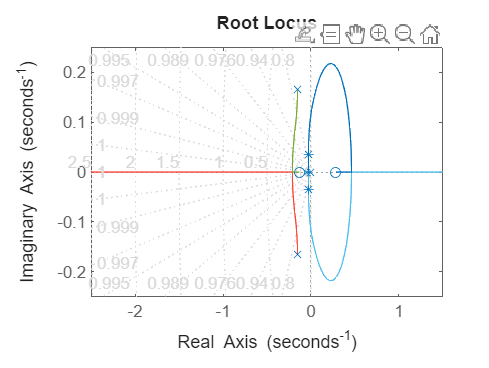

figure(3)
rlocus(-Gol)
grid on
hold on 
plot([-sigma  -sigma],[wd  -wd],'*')
% axis([-0.5 0.2 -0.1  0.1])
hold off

Kp = -0.000129 % PI

Kp = -1.2900e-04

Kp= -0.00162% -0.000102;

Kp = -0.0016

%En lazo cerrado
Glc = feedback(Kp*Gol,1)

figure(2)
step(Glc);
title('Respuesta de lazo cerrado')
grid on

T_r = 54.9 - 7.27

T_r = 47.6300

T_c = 4

T_c = 4

# Servosistema

## Espacio de estados

A = [0 1 0; 0 0 1; -0.002795 -0.06843 -0.3645]

A =          0    1.0000         0
         0         0    1.0000
   -0.0028   -0.0684   -0.3645



B = [0
     0
     1]

B =      0
     0
     1


C = [-2.149 7.715 0]

C =    -2.1490    7.7150         0



Tes = 100 

Tes = 100

Mp = 0.1

Mp = 0.1000


% Factor de amortiguamiento relativo
far = -log(Mp)/sqrt(pi^2 + log(Mp)^2)

far = 0.5912


sigma = 4/Tes

sigma = 0.0400

wn = sigma/far

wn = 0.0677

fi = acos(far)

fi = 0.9383

% Tiempo de subida
Tr = exp(fi/tan(fi))/wn

Tr = 29.3977


% Tr = 29.4 
T = 3; % Aprox. Tr/10

% Muestreo del sistema
FI = eye(3)*T + A*T^2/2 + A^2*T^3/6 + A^3*T^4/24

FI =     2.9906    4.2690    3.2698
   -0.0091    2.7668    3.0772
   -0.0086   -0.2197    1.6452


G = eye(3) + A*FI

G =     0.9909    2.7668    3.0772
   -0.0086    0.7803    1.6452
   -0.0046   -0.1212    0.1806


H = FI*B

H =     3.2698
    3.0772
    1.6452


### Servosistema

% Servosistema agregando integrador
GN = [G zeros(3, 1)
    -C*G 1]

GN =     0.9909    2.7668    3.0772         0
   -0.0086    0.7803    1.6452         0
   -0.0046   -0.1212    0.1806         0
    2.1957   -0.0740   -6.0796    1.0000


HN = [H
    -C*H]

HN =     3.2698
    3.0772
    1.6452
  -16.7138


% Controlabilidad
CoN = [HN GN*HN GN^2*HN GN^3*HN]

CoN =     3.2698   16.8165   30.4377   38.1300
    3.0772    5.0796    3.6696    1.4347
    1.6452   -0.0908   -0.7093   -0.7127
  -16.7138  -19.7640   17.3360   88.2089


det_CoN = det(CoN)

det_CoN = -4.5573e+03

% Dinámica deseada
wd = -pi*sigma/log(Mp)

wd = 0.0546

s1 = -sigma + wd*1i

s1 = -0.0400 + 0.0546i

s2 = -sigma - wd*1i

s2 = -0.0400 - 0.0546i

s3 = -5*sigma

s3 = -0.2000

s4 = -8*sigma % más alejado

s4 = -0.3200


% Polos discretos
z1 = exp(T*s1)

z1 = 0.8751 + 0.1446i

z2 = exp(T*s2)

z2 = 0.8751 - 0.1446i

z3 = exp(T*s3)

z3 = 0.5488

z4 = exp(T*s4)

z4 = 0.3829


% Diseño
KN = acker(GN, HN, [z1 z2 z3 z4])

KN =     0.0036    0.0196    0.1235    0.0003


K2 = KN(1:3)

K2 =     0.0036    0.0196    0.1235


K1 = -KN(4)

K1 = -3.0186e-04

### Observador

% Observabilidad
Ob = [C
      C*G
      C*G^2]

Ob =    -2.1490    7.7150         0
   -2.1957    0.0740    6.0796
   -2.2042   -6.7541   -5.5367


detOb = det(Ob) % detOb = -284.54 != 0 -> Observable

detOb = -284.5418


% Polos del observador
so1 = 2*s1;
so2 = 2*s2;
so3 = 2*s3;

zo1 = exp(T*so1)

zo1 = 0.7448 + 0.2530i

zo2 = exp(T*so2)

zo2 = 0.7448 - 0.2530i

zo3 = exp(T*so3)

zo3 = 0.3012


% Obs en tiempo discreto
Ke = acker(G', C', [zo1 zo2 zo3])'

Ke =    -0.0363
    0.0107
   -0.0048
